# In the Name of God

## CA2

## Amir Hussain Birjandi - 810198367

### Problem 1

#### part1)

disp('part 1:')

part 1:


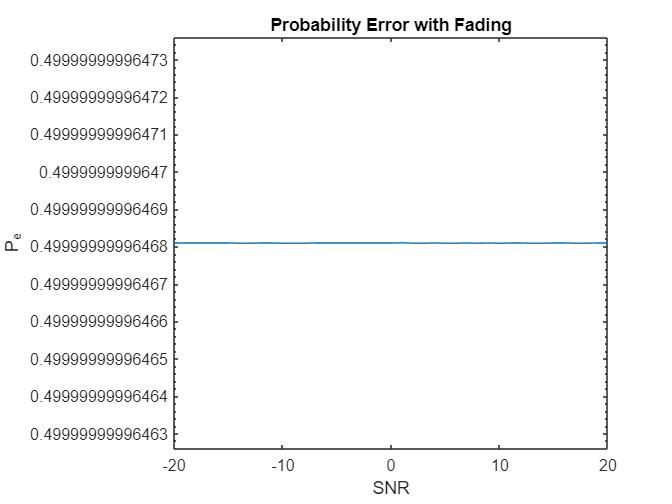

SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
a = -inf;
b = inf;
Pe_integralvalue = zeros(1,numel(SNR_db));
for i=1:numel(SNR_db)
    Pe_integralvalue(i) = integral(@(hm) 1/sqrt(pi)*qfunc(hm.*sqrt(2*SNR(i))).*exp(-hm.^2), a, b);
end
semilogy(SNR_db,Pe_integralvalue);
title('Probability Error with Fading')
ylabel('P_{e}')
xlabel('SNR')

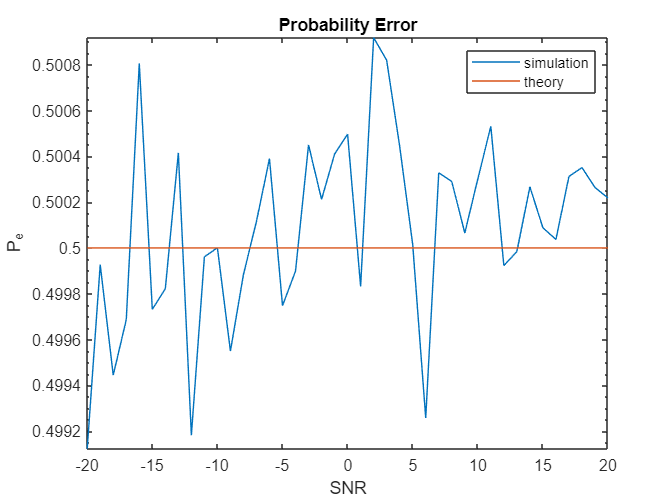

SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);

n = 1e6;
x = randi([0,1],n,1);
x_c = zeros(n,1);
a = 1;

for i=1:n
    if(x(i) == 0)
        x_c(i) = -a;
    else
        x_c(i) = a;
    end
end
N0_vector = (a^2)./SNR;
h = (randn(n,1)+1i*randn(n,1))*sqrt(0.5);

Pe = zeros(numel(SNR_db),1);
xhat = zeros(n,1);
detected = zeros(n,1);


for j=1:numel(SNR_db)
    w = (randn(n,1)+1i.*randn(n,1)).*sqrt(N0_vector(j)/2);
    y = x_c.*h + w;
    for k=1:n
        if(real(y(k,1))<0)
            detected(k) = 0;
        else
            detected(k) = 1;
        end
    end
    Pe(j) = 1 - sum(x==detected)/numel(x);
end

semilogy(SNR_db,Pe);
hold on
plot(SNR_db,Pe_integralvalue);
hold off

legend('simulation','theory')
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

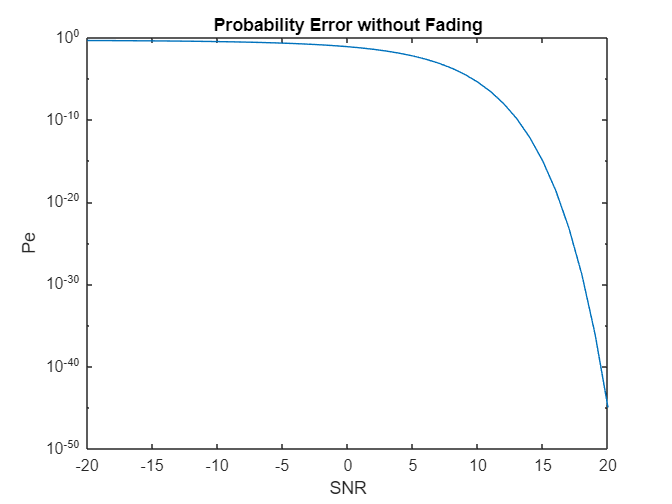


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Pe = qfunc(sqrt(2*SNR));
semilogy(SNR_db,Pe);
title('Probability Error without Fading')
ylabel('Pe')
xlabel('SNR')

#### part2)

disp('Part 2:')

Part 2:


#### 1)

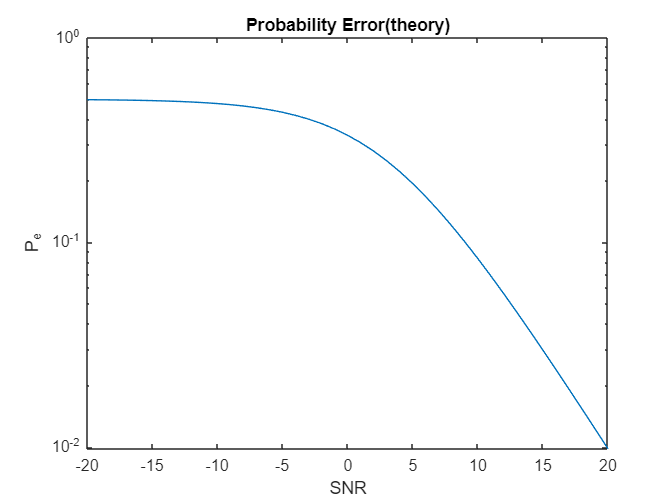

SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);

Pe = 1./(2+SNR);
semilogy(SNR_db,Pe);
title('Probability Error(theory)')
ylabel('P_{e}')
xlabel('SNR')

#### 2)

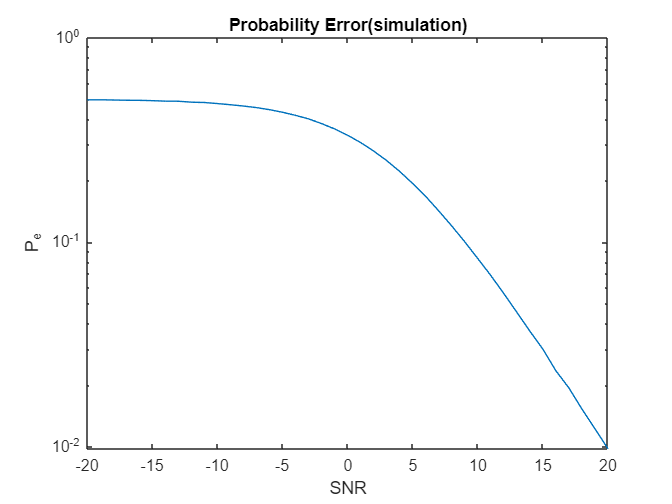

SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);

n = 1e6;
x = randi([0,1],n,1);

x_c = zeros(n,2);
a = 1;

for i=1:n
    if(x(i) == 0)
        x_c(i,:) = [a,0];
    else
        x_c(i,:) = [0,a];
    end
end
N0_vector = (a^2)./SNR;
h = (randn(n,2)+1i*randn(n,2))*sqrt(0.5);
Pe1 = zeros(numel(SNR_db),1);
xhat = zeros(n,1);

for j=1:numel(SNR_db)
    w = (randn(n,2)+1i.*randn(n,2)).*sqrt(N0_vector(j)/2);
    y = x_c.*h + w;
    y2s = abs(y).^2;
    for k=1:n
        if(y2s(k,1)>y2s(k,2))
            xhat(k) = 1;
        else
            xhat(k) = 0;
        end
    end
    Pe1(j) = sum(x==xhat)/numel(x);
end
semilogy(SNR_db,Pe1);
title('Probability Error(simulation)')
ylabel('P_{e}')
xlabel('SNR')

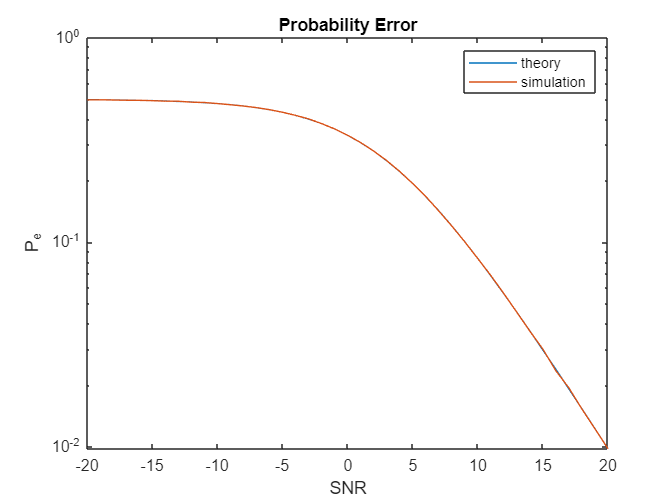

semilogy(SNR_db,Pe);
hold on
semilogy(SNR_db,Pe1);
hold off
legend('theory','simulation')
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

#### part3)

disp('Part 3:')

Part 3:


#### 1)

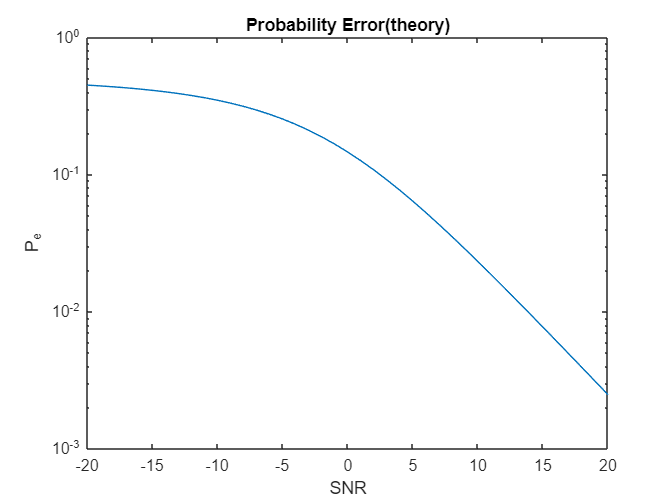

SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);


Pe_integralvalue = zeros(1,numel(SNR_db));
for i=1:numel(SNR_db)
    f = @(hmr,hmi) qfunc(sqrt(2*SNR(i).*(hmr.^2+hmi.^2))).*exp(-(hmr.^2+hmi.^2));
    Pe_integralvalue(i) = integral2(f, -Inf, Inf, -Inf, Inf);
end
semilogy(SNR_db,1/pi*Pe_integralvalue);
title('Probability Error(theory)')
ylabel('P_{e}')
xlabel('SNR')

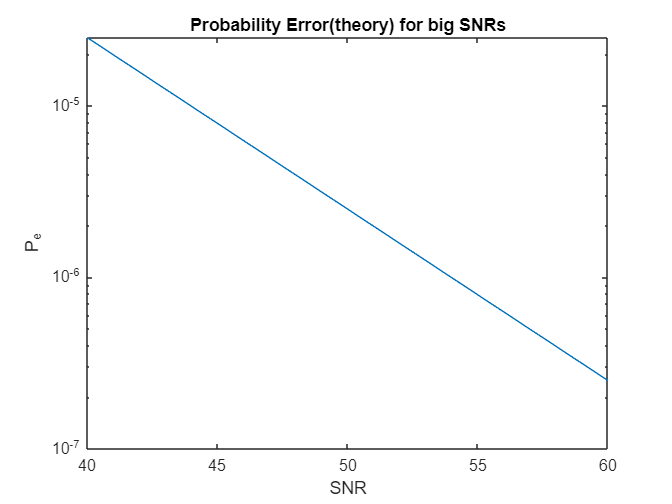

bigSNR_db = 40:1:60;
SNR = 10.^(bigSNR_db./10);


Pe_integralvalue1 = zeros(1,numel(bigSNR_db));
for i=1:numel(bigSNR_db)
    f = @(hmr,hmi) qfunc(sqrt(2*SNR(i).*(hmr.^2+hmi.^2))).*exp(-(hmr.^2+hmi.^2));
    Pe_integralvalue1(i) = integral2(f, -Inf, Inf, -Inf, Inf);
end
semilogy(bigSNR_db,1/pi*Pe_integralvalue1);
title('Probability Error(theory) for big SNRs')
ylabel('P_{e}')
xlabel('SNR')

#### 2)

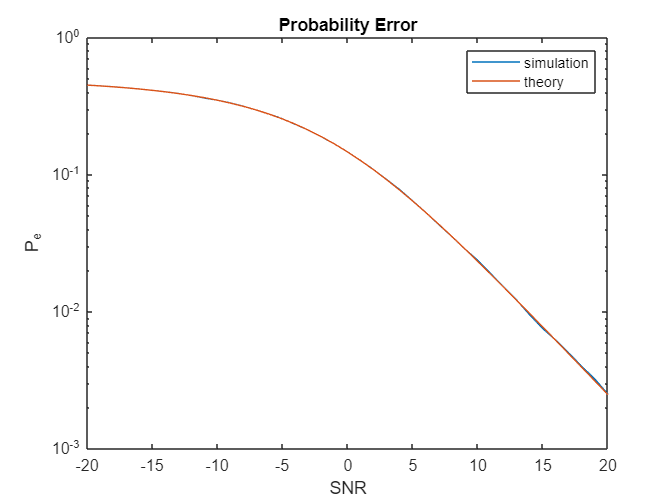


SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);

n = 1e6;
x = randi([0,1],n,1);
x_c = zeros(n,1);
a = 1;

for i=1:n
    if(x(i) == 0)
        x_c(i) = -a;
    else
        x_c(i) = a;
    end
end
N0_vector = (a^2)./SNR;
h = (randn(n,1)+1i*randn(n,1))*sqrt(0.5);

Pe = zeros(numel(SNR_db),1);
xhat = zeros(n,1);
detected = zeros(n,1);


for j=1:numel(SNR_db)
    w = (randn(n,1)+1i.*randn(n,1)).*sqrt(N0_vector(j)/2);
    y = x_c.*h + w;
    xhat = y.*conj(h)./abs(h).^2;
    for k=1:n
        if(real(xhat(k,1))<0)
            detected(k) = 1;
        else
            detected(k) = 0;
        end
    end
    Pe(j) = sum(x==detected)/numel(x);
end

semilogy(SNR_db,Pe);
hold on
plot(SNR_db,1/pi*Pe_integralvalue);
hold off

legend('simulation','theory')
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

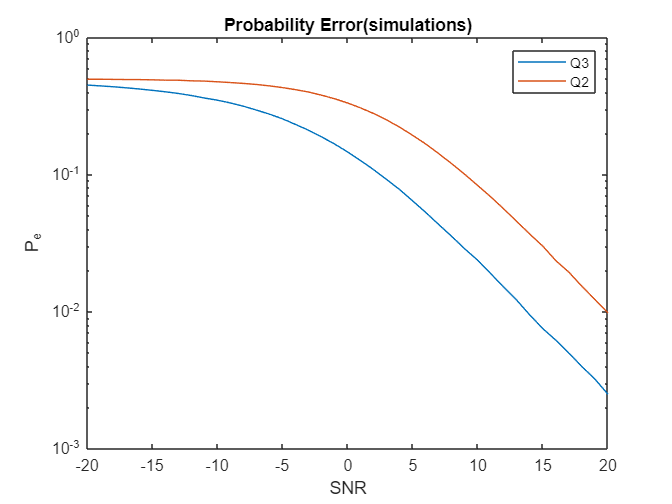


semilogy(SNR_db,Pe);
hold on
plot(SNR_db,Pe1);
hold off
legend('Q3','Q2')
title('Probability Error(simulations)')
ylabel('P_{e}')
xlabel('SNR')

ratio = 10*log10(Pe1(end)/Pe(end));
display(ratio);

ratio = 5.9363

#### part4)

1)

theory:

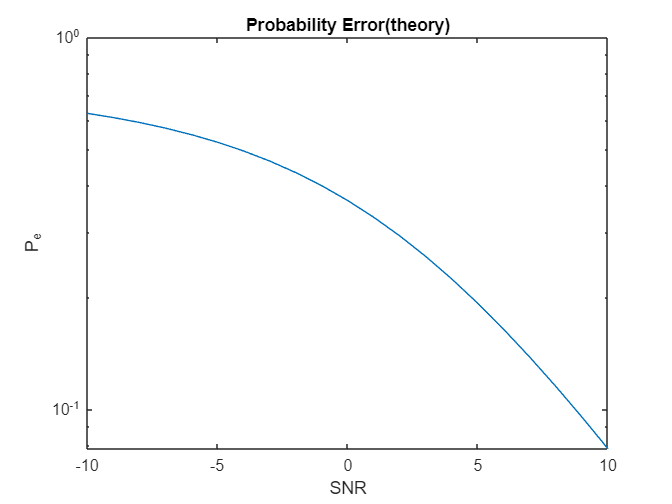

SNR_db = -10:1:10;
SNR = 10.^(SNR_db./10);
dhr = 0.01;
dhi = 0.01;
hr = -10:dhr:10;
hi = -10:dhi:10;

Pc_integralvalue = zeros(1,numel(SNR_db));
for i=1:numel(SNR_db)
      f = @(hr,hi) 1/pi * (1-qfunc(sqrt(SNR(i)*(hr.^2 + hi.^2)))).^2 .* exp(-hr.^2 - hi.^2);
      Pc_integralvalue(i) = 1/pi * sum(sum((1-qfunc(sqrt(SNR(i)*(hr.^2 + hi.^2.')))).^2 .* exp(-hr.^2 - hi.^2.') * dhr * dhi));
end
semilogy(SNR_db,1 - Pc_integralvalue);
title('Probability Error(theory)')
ylabel('P_{e}')
xlabel('SNR')

simulation:

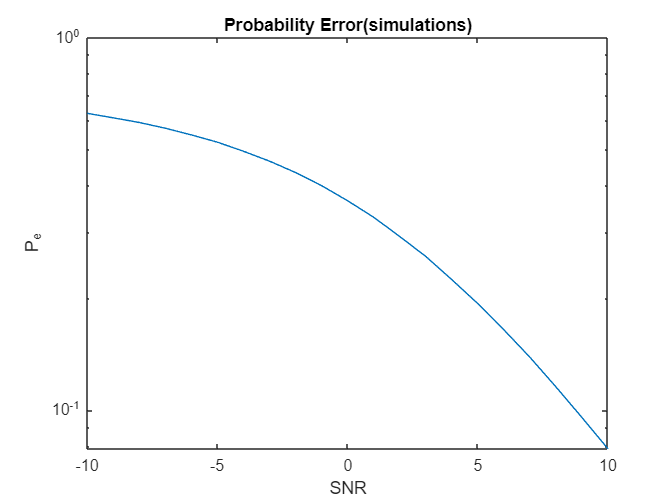

SNR_db = -10:1:10;
SNR = 10.^(SNR_db./10);

n = 1e6;
x = randi([0,3],n,1);
x_c = zeros(n,2);
a = 1;

for i=1:n
    if(x(i) == 0)
        x_c(i,:) = (1+1i)/sqrt(2);
    elseif(x(i) == 1)
        x_c(i,:) = (-1+1i)/sqrt(2);
    elseif(x(i)==2)
        x_c(i,:) = (-1-1i)/sqrt(2);
    elseif(x(i)==3)
        x_c(i,:) = (1-1i)/sqrt(2);
    end
end

N0_vector = (a^2)./SNR;
h = (randn(n,1)+1i*randn(n,1))*sqrt(0.5);

Pe = zeros(numel(SNR_db),1);
xhat = zeros(n,1);
detected = zeros(n,1);


for j=1:numel(SNR_db)
    w = (randn(n,1)+1i.*randn(n,1)).*sqrt(N0_vector(j)/2);
    y = x_c.*h + w;
    xhat = y.*conj(h)./abs(h).^2;
    for k=1:n
        if(real(xhat(k,1))<0)
           if(imag(xhat(k,1))<0)
               detected(k) = 2;
           else
               detected(k) = 1;
           end
        else
            if(imag(xhat(k,1))<0)
               detected(k) = 3;
            else
               detected(k) = 0;
            end
        end
    end
    Pe(j) = 1 - sum(x==detected)/numel(x);
end
semilogy(SNR_db,Pe);
title('Probability Error(simulations)')
ylabel('P_{e}')
xlabel('SNR')

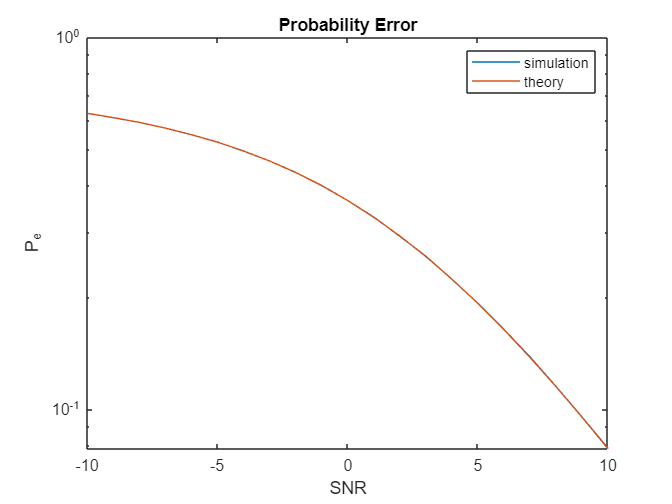



semilogy(SNR_db,Pe);
hold on
plot(SNR_db,1 - Pc_integralvalue);
hold off

legend('simulation','theory')
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

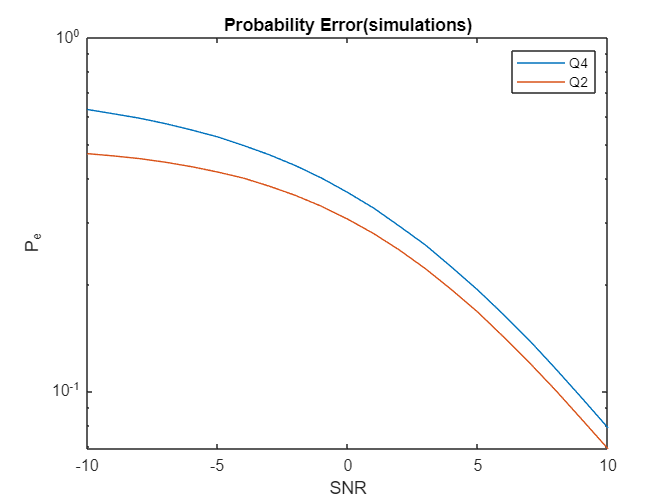


semilogy(SNR_db,Pe);
hold on
plot(SNR_db,Pe1(12:32));
hold off
legend('Q4','Q2')
title('Probability Error(simulations)')
ylabel('P_{e}')
xlabel('SNR')

ratio = 10*log10(Pe1(end)/Pe(end));
display(ratio);

ratio = -9.0599

#### part5)

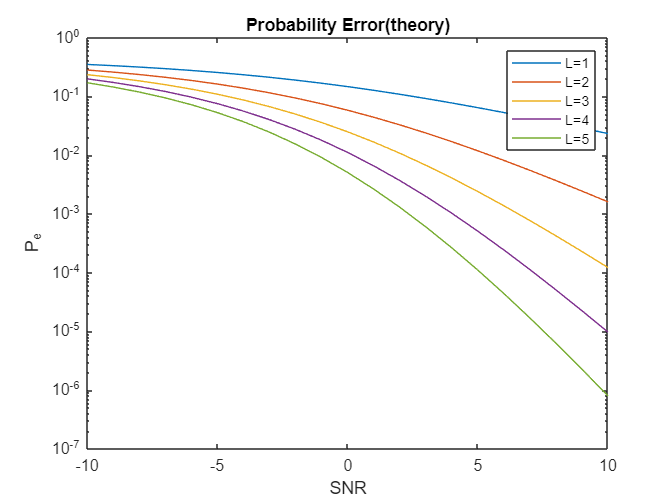

SNR_db = -10:1:10;
SNR = 10.^(SNR_db./10);
a = 0;
b =1e5;
L = 5;

Pe_integralvalue = zeros(L,numel(SNR_db));
for l=1:L
    for i=1:numel(SNR_db)
            Pe_integralvalue(l,i) = 1/factorial(l-1) .* integral(@(h) qfunc(sqrt(h.*2*SNR(i))).*h.^(l-1).*exp(-h), a, b);
    end
end
semilogy(SNR_db,Pe_integralvalue);
legend('L=1','L=2','L=3','L=4','L=5')
title('Probability Error(theory)')
ylabel('P_{e}')
xlabel('SNR')

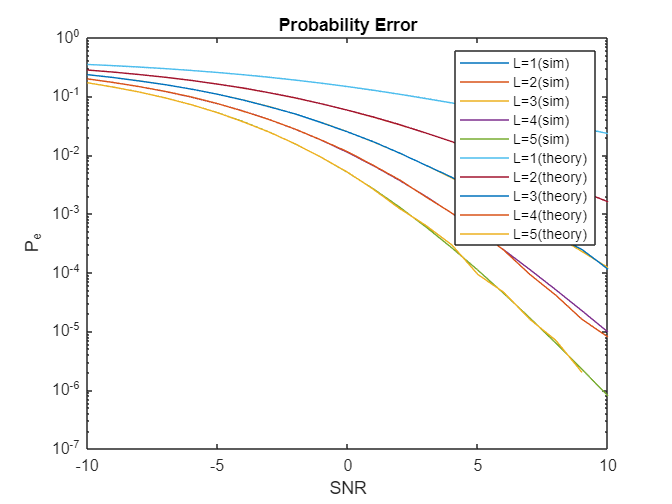

SNR_db = -10:1:10;
SNR = 10.^(SNR_db./10);

Pe = zeros(numel(SNR_db),L);


for l=1:L
    n = 1e6;
    x = randi([0,1],n,1);
    x_c = zeros(n,1);
    a = 1;
    
    for i=1:n
        if(x(i) == 0)
            x_c(i) = -a;
        else
            x_c(i) = a;
        end
    end
    
    N0_vector = (a^2)./SNR;
    h = (randn(n,l)+1i*randn(n,l))*sqrt(0.5);
    
    xhat = zeros(n,1);
    detected = zeros(n,1);    

    for j=1:numel(SNR_db)
        w = (randn(n,l)+1i.*randn(n,l)).*sqrt(N0_vector(j)/2);
        y = x_c.*h + w;
        theta = angle(h);
        alpha = abs(h) .* exp(-1i*theta);
        gamasigma = sum(y .* alpha, 2);
        xhat = real(gamasigma) > 0;
        Pe(j,l) = sum(x ~= xhat)/numel(x);
    end
end
semilogy(SNR_db,Pe_integralvalue);
hold on
semilogy(SNR_db,Pe);
hold off
legend('L=1(sim)','L=2(sim)','L=3(sim)','L=4(sim)','L=5(sim)','L=1(theory)','L=2(theory)','L=3(theory)','L=4(theory)','L=5(theory)')
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

#### part6)

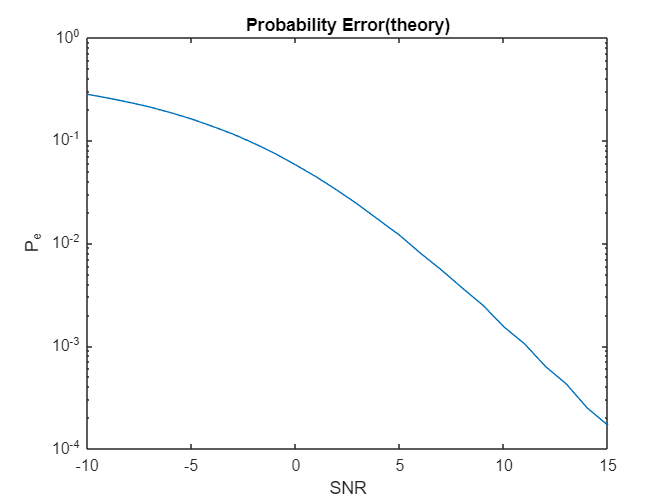

SNR_db = -10:1:15;
SNR = 10.^(SNR_db./10);

Pe = zeros(numel(SNR_db),1);

n = 1e6;
x = randi([0,1],n,1);
x_c = zeros(n,1);
a = 1;

for i=1:n
    if(x(i) == 0)
        x_c(i) = -a;
    else
        x_c(i) = a;
    end
end

N0_vector = (a^2)./SNR;
h = (randn(n/2,2)+1i*randn(n/2,2))*sqrt(0.5);
x1 = reshape(x_c,[2,n/2]);
x2 = [-conj(x1(2,:)); conj(x1(1,:))];

for j=1:numel(SNR_db)
    w = (randn(n/2,2)+1i.*randn(n/2,2)).*sqrt(N0_vector(j)/2);
    y1 = sum(transpose(h) .* x1,1) + transpose(w(:,1)); 
    y2 = sum(transpose(h) .* x2,1) + transpose(w(:,2));
    m1 = conj(transpose(h(:,1))) .* y1 + transpose(h(:,2)) .* conj(y2);
    m2 = conj(transpose(h(:,2))) .* y1 - transpose(h(:,1)) .* conj(y2);
    z(1:2:n) = m1;
    z(2:2:n) = m2;
    xhat = real(z) > 0;
    Pe(j) = sum(transpose(x) ~= xhat)/numel(x);
end

semilogy(SNR_db,Pe);
title('Probability Error(theory)')
ylabel('P_{e}')
xlabel('SNR')

## Problem 2

## Frequency selective channel

#### part5)

N = 1e7;
nc = 1e4;
Blocks = N/nc;
L = 200;
SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);
x = randi([0,1],1,N);
x(x==0) = -1;


simulating

Pe = zeros(1,41);
i = 0;
channel_capacitance = zeros(length(-20:20),Blocks);
for SNR_dB = -20:20
    i = i + 1;
    errors = 0;
    Pmax = nc;
    SNR = 10^(SNR_dB/10);
    N0 = Pmax / (nc * SNR);
    for num_block = 0:Blocks-1
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, nc);
        myfun = @(lambda) Pmax - sum(max(1/lambda - N0./(abs(H).^2),0));
        fun = @(lambda) myfun(lambda); 
        lambda0 = fzero(fun,0.9);
        Pi = max(1/lambda0 - N0./(abs(H).^2),0);
        a = x(num_block*nc+1:(num_block+1)*nc);
        a_wat = a .* sqrt(Pi) .* exp(-1i.*angle(H));
        A = ifft(a_wat,nc);
        cp = A(end-L+2:end);
        A_cp = [cp, A];
        w = sqrt(0.5*N0) * (randn(1,nc) + randn(1,nc)*1i);
        y = conv(A_cp,h) ;
        y_cp = y(L:L+nc-1) + w;
        Y = fft(y_cp,nc);
        Z=Y;
        Z(real(Z) > 0) = 1;
        Z(real(Z) < 0) = -1;
        errors = errors + sum(a ~= Z);
        channel_capacitance(SNR_dB+21,num_block+1) = sum(log2(1 + Pi.*abs(H).^2./N0));
    end
    Pe(i) = errors/N;
end

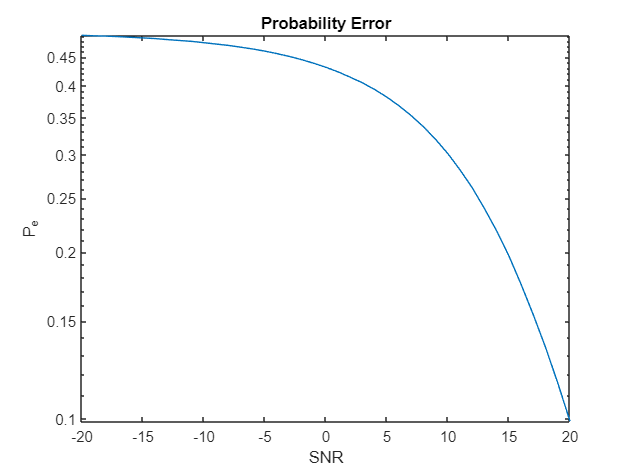


semilogy(SNR_db,Pe);
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

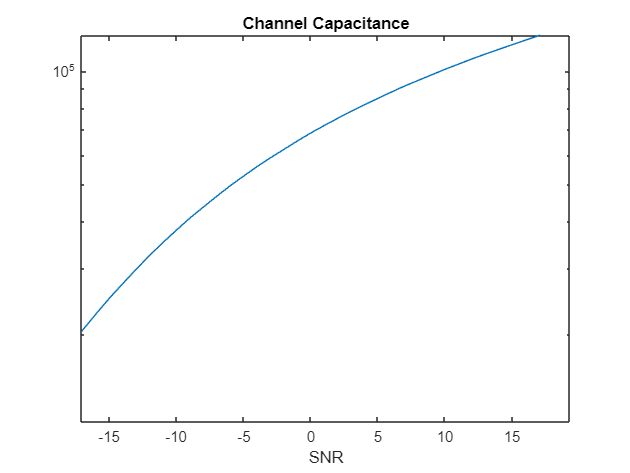

semilogy(SNR_db,mean(channel_capacitance,2));
title('Channel Capacitance')
ylabel(' ')
xlabel('SNR')

#### Part6)

N = 2e6;
nc = 1e4;
Blocks = N/nc;
L = 200;
SNR_db = -20:1:20;
diversity = 10;

Pe = zeros(1,41);
i = 0;
x = randi([0,1],1,N);
x(x==0) = -1;

for SNR_dB = -20:20
    i = i + 1;
    errors = 0;
    Pmax = nc;
    SNR = 10^(SNR_dB/10);
    N0 = Pmax / (nc * SNR);

    for num_block = 0:Blocks-1
        
        a = x(num_block*nc+1:(num_block+1)*nc);
        A = ifft(a,nc);
        cp = A(end-L+2:end);
        A_cp = [cp, A];
        sumgamasigma = zeros(1,nc);

        for d=1:diversity

            h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
            w = sqrt(0.5*N0) * (randn(1,nc) + randn(1,nc)*1i);
            H = fft(h,nc);
            y = conv(A_cp,h);
            y_cp = y(L:L+nc-1) + w;
            Y = fft(y_cp,nc);
            theta = angle(H);
            alpha = 1/N0 * abs(H).^2 .* exp(-1i*theta);
            gamasigma = sum(Y .* alpha, 1);
            sumgamasigma = sumgamasigma + gamasigma;
        end
        Z(real(sumgamasigma) > 0) = 1;
        Z(real(sumgamasigma) < 0) = -1;
        errors = errors + sum(a ~= Z);
    end
    Pe(i) = errors/N;
end

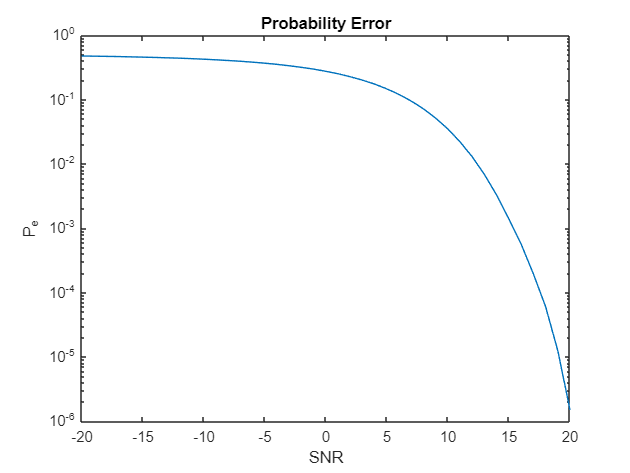


semilogy(SNR_db,Pe);
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

#### Part7)

N = 1e7;
nc = 1e4;
Blocks = N/nc;
L = 200;
SNR_db = -20:1:20;
SNR = 10.^(SNR_db./10);
x = randi([0,1],1,N);
x(x==0) = -1;

#### ZF

Pe = zeros(1,41);
i = 0;
for SNR_dB = -20:20
    i = i + 1;
    errors = 0;
    Pmax = nc;
    SNR = 10^(SNR_dB/10);
    N0 = Pmax / (nc * SNR);
    for num_block = 0:Blocks-1
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, nc);
        a = x(num_block*nc+1:(num_block+1)*nc);
        A = ifft(a,nc);
        cp = A(end-L+2:end);
        A_cp = [cp, A];
        w = sqrt(0.5*N0) * (randn(1,nc) + randn(1,nc)*1i);
        y = conv(A_cp,h) ;
        y_cp = y(L:L+nc-1) + w;
        Y = fft(y_cp,nc);
        Z= Y ./ H;
        Z(real(Z) > 0) = 1;
        Z(real(Z) < 0) = -1;
        errors = errors + sum(a ~= Z);
    end
    Pe(i) = errors/N;
end

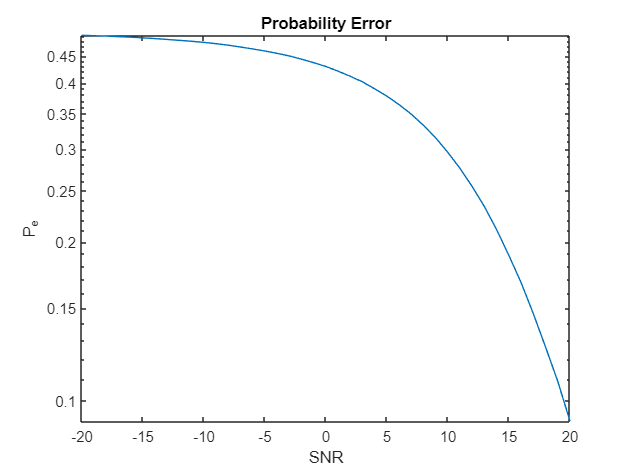

semilogy(SNR_db,Pe);
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

#### MMSE

Pe = zeros(1,41);
i = 0;
for SNR_dB = -20:20
    i = i + 1;
    errors = 0;
    Pmax = nc;
    SNR = 10^(SNR_dB/10);
    N0 = Pmax / (nc * SNR);
    for num_block = 0:Blocks-1
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, nc);
        a = x(num_block*nc+1:(num_block+1)*nc);
        A = ifft(a,nc);
        cp = A(end-L+2:end);
        A_cp = [cp, A];
        w = sqrt(0.5*N0) * (randn(1,nc) + randn(1,nc)*1i);
        y = conv(A_cp,h) ;
        y_cp = y(L:L+nc-1) + w;
        Y = fft(y_cp,nc);
        Z= Y .* conj(H)./(abs(H).^2 + N0/1);
        Z(real(Z) > 0) = 1;
        Z(real(Z) < 0) = -1;
        errors = errors + sum(a ~= Z);
    end
    Pe(i) = errors/N;
end

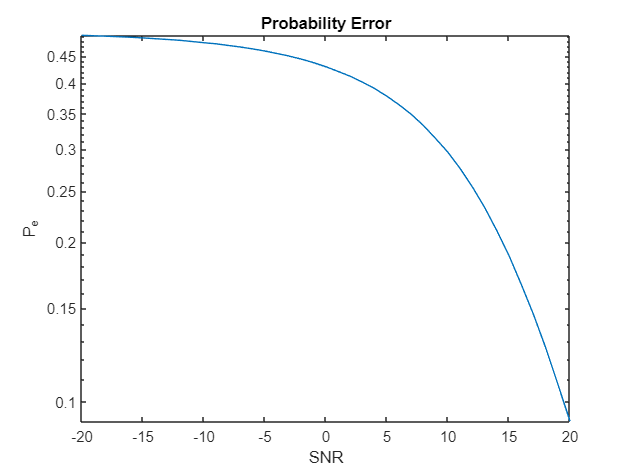

semilogy(SNR_db,Pe);
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')

#### Part8

Pe = zeros(1,41);
i = 0;
for SNR_dB = -20:20
    i = i + 1;
    errors = 0;
    Pmax = nc;
    SNR = 10^(SNR_dB/10);
    N0 = Pmax / (nc * SNR);
    for num_block = 0:Blocks-1
        h = sqrt(0.5) * (randn(1,L) + randn(1,L)*1i);
        H = fft(h, nc);
        a = x(num_block*nc+1:(num_block+1)*nc);
        A = ifft(a,nc);
        maxA = max(abs(A));
        angles = angle(A);
        for l=1:numel(A)
            if(abs(A(l)) > 0.5 * maxA)
                A(l) = 0.5*maxA * angles(l); 
            end
        end
        cp = A(end-L+2:end);
        A_cp = [cp, A];
        w = sqrt(0.5*N0) * (randn(1,nc) + randn(1,nc)*1i);
        y = conv(A_cp,h) ;
        y_cp = y(L:L+nc-1) + w;
        Y = fft(y_cp,nc);
        Z= Y .* conj(H)./(abs(H).^2 + N0/1);
        Z(real(Z) > 0) = 1;
        Z(real(Z) < 0) = -1;
        errors = errors + sum(a ~= Z);
    end
    Pe(i) = errors/N;
end

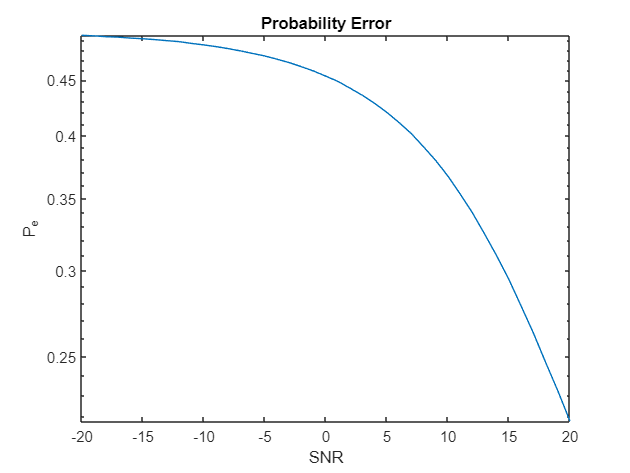

semilogy(SNR_db,Pe);
title('Probability Error')
ylabel('P_{e}')
xlabel('SNR')